[**MIT License**](https://github.com/cdslaborg/paramonte#license)

[**ParaMonte: plain powerful parallel Monte Carlo library**](https://github.com/cdslaborg/paramonte)**.**

**Copyright (C) 2012-present, **[**The Computational Data Science Lab**](https://www.cdslab.org/#about)

[**https://github.com/cdslaborg/paramonte**](https://github.com/cdslaborg/paramonte)

# Making histogram plots with the ParaMonte visualization tools

**NOTE**

If you are viewing an HTML version of this MATLAB live script on the web, you can download the corresponding MATLAB live script `visualization_histogram.mlx` file to this HTML page at,

[https://github.com/cdslaborg/paramontex/tree/master/MATLAB/mlx](https://github.com/cdslaborg/paramontex/tree/master/MATLAB/mlx)

Once you download the file, open it in MATLAB to view and interact with its contents, which is the same as what you see on this page. 

First, let's clean up the MATLAB environment and make sure the path to the ParaMonte library is in MATLAB's path list.

clc;
clear all;
close all;
format compact; format long;

%%%%%%%%%%%% IMPORTANT %%%%%%%%%%%%%
% Set the path to the ParaMonte library:
% Change the following path to the ParaMonte library root directory, 
% otherwise, make sure the path to the ParaMonte library is already added
% to MATLAB's path list.

pmlibRootDir = './';
addpath(genpath(pmlibRootDir),"-begin");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% change MATLAB's working directory to the folder containing this script
% if MATLAB Live Scripts did not create a temporary folder, we would not
% have all of these problems!

try
    setwd; % This is a MATLAB script that you can download from the same GitHub location given in the above.
catch % alas, we will have to run the simulations in MATLAB Live Script's temporary folder
    filePath = mfilename('fullpath');
    [currentDir,fileName,fileExt] = fileparts(filePath); cd(currentDir);
    cd(fileparts(mfilename('fullpath'))); % Change working directory to source code directory.
end

## ParaMonte's default visualization tools

The ParaMonte library ships with several visualization tools that automate much of the MATLAB coding required to visualize the output of the simulations performed by the ParMonte library samplers. 

By replacing the input dataFrame to these tools and following the conventions of the ParaMonte library, one can also use these visualization tools for any dataset that may not have been generated by the ParaMonte library.

Consider the following Markov chain on the web in **compact** format generated by the **ParaDRAM** sampler of the ParaMonte library to sample a MultiVariate Normal distribution. Since this is a chain file as inidicated by its suffix `"_chain.txt"` We will read this file via the ParaDRAM sampler's `readChain()` method.

pm = paramonte();
pmpd = pm.ParaDRAM();
url = "https://github.com/cdslaborg/paramontex/raw/master/MATLAB/mlx/sampling_multivariate_normal_density_function_via_paradram/mvn_serial_process_1_chain.txt";
pmpd.readChain(url); % read the chain file from the web


ParaDRAM - WARNING: The ParaDRAM input simulation specification `pmpd.spec.outputDelimiter` is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...

ParaDRAM - NOTE: 1 files detected matching the pattern: 
ParaDRAM - NOTE: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\https:\\github.com\cdslaborg\paramontex\raw\master\MATLAB\mlx\sampling_multivariate_normal_density_function_via_paradram\mvn_serial_process_1_chain.txt*"

ParaDRAM - NOTE: processing file: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\temp_20200917_011802_399.txt"
ParaDRAM - NOTE: reading the file contents... 
ParaDRAM - NOTE: done in 0.511760 seconds.
ParaDRAM - NOTE: ndim = 4, count = 30000

ParaDRAM - NOTE: computing the sample correlation matrix...

ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - N

This method automatically generates a set of tools that can be used to visualize the contents of the compact chain file. Note that these visualization tools are not unique to this particular method of the ParaDRAM sampler or other ParaMonte samplers. For the sake of illustration however, we will create plots using the above dataset read via `readChain()` method of the ParaDRAM routine.

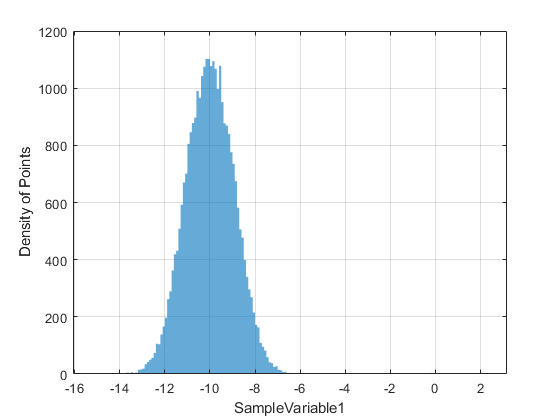

chain = pmpd.chainList{1};
chain.plot.histogram.make();

To draw the a histogram, the ParaMonte visualizer utilizes the` histogram()` function of MATLAB. One can pass pairs of (key,value) properties to this MATLAB function by defining those **keyword** properties in the histogram component of the plot object. There are a few properties defined already in this structure,

chain.plot.histogram.histogram.kws

ans = struct with fields:
    edgeColor: "none"
    faceAlpha: 0.600000000000000
    faceColor: "auto"

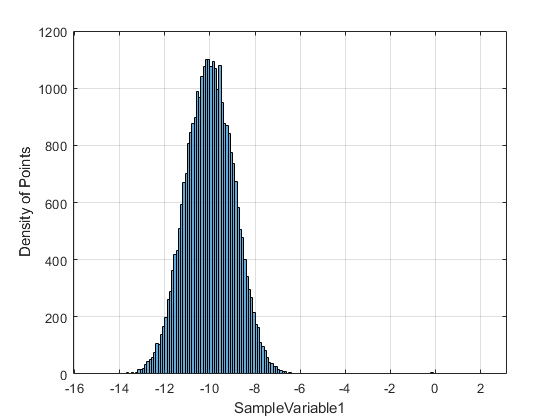

chain.plot.histogram.histogram.kws.lineWidth = 0.5; % add new histogram attribute
chain.plot.histogram.histogram.kws.edgeColor = "black";
chain.plot.histogram.make();

To **reset** the properties of the plot object to the default settings, try, 

chain.plot.histogram.reset();

ParaDRAM - NOTE: resetting the properties of the histogram plot...


To reset the entire plot object including reading the data again from the input dataFrame, try, 

chain.plot.histogram.reset("hard");

ParaDRAM - NOTE: creating the histogram plot object from scratch...


Remember that a handle to all objects in the plot is also stored in the `currentFig` component of the object. Most of the properties of the figure, axes, and the plots can be also changed directly via these handles. For example, to change the colorbar label, we could try,

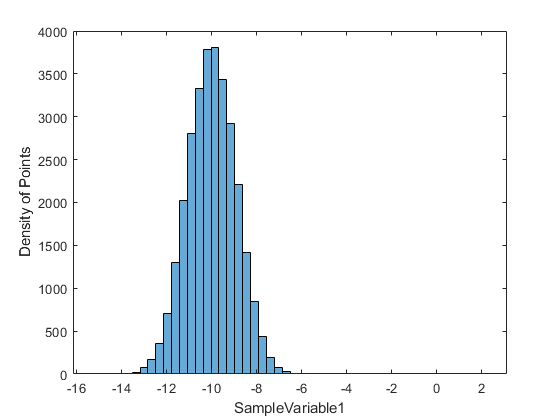

chain.plot.histogram.make();
chain.plot.histogram.currentFig.histogram{1}.EdgeColor = "black";
chain.plot.histogram.currentFig.histogram{1}.NumBins = 50;
grid off;

## Choosing different columns of data to plot

By default, the column named the first two variables of the sampled space are shown in the plot. This can be readily changed to any paris of variables, like, 

chain.df.Properties.VariableNames

ans = 1×11 cell array
    {'ProcessID'}    {'DelayedRejectionStage'}    {'MeanAcceptanceRate'}    {'AdaptationMeasure'}    {'BurninLocation'}    {'SampleWeight'}    {'SampleLogFunc'}    {'SampleVariable1'}    {'SampleVariable2'}    {'SampleVariable3'}    {'SampleVariable4'}

chain.plot.histogram.reset();

ParaDRAM - NOTE: resetting the properties of the histogram plot...


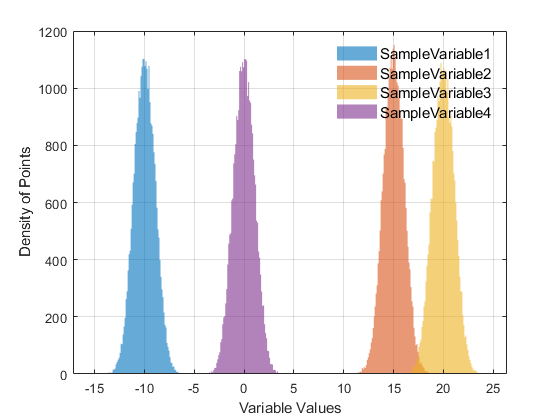

chain.plot.histogram.legend.enabled = true;
chain.plot.histogram.legend.kws.location = "northeast";
chain.plot.histogram.make( "xcolumns", ["SampleVariable1", 9:11]);

Notice the possibility of use of both **column indices** and **column names** to point to a data column in the dataFrame.

## Plotting specific rows of data

Selected rows of data can be also plotted, if not all data observations have to be included. For example, we can exclude the burnin episode as determined by the ParaMonte sampler, 

chain.plot.histogram.reset();

ParaDRAM - NOTE: resetting the properties of the histogram plot...


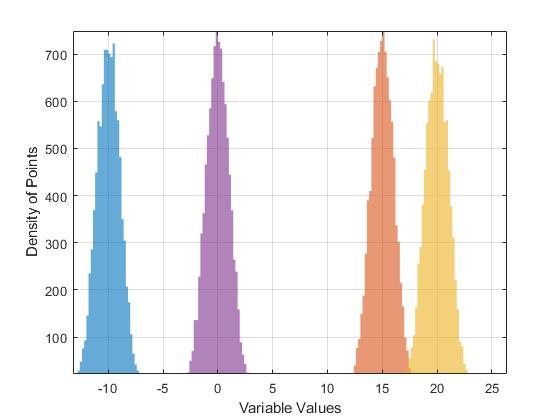

burnin = chain.df.BurninLocation(end); % get the inferred burning location at the end of the chain

chain.plot.histogram.rows = burnin:3:chain.count; % plot every one out of 10 data rows, starting from the burnin location to the end of the chain.
chain.plot.histogram.make("xcolumns", 8:11);

## Adding targets to the plot

One can also **add target values** to the plots, use the `target()` component of the plot object. For example, one may want to add a horizontal line as the target, representing for example the **mean** and the **standard deviation** of the sample, 

chain.plot.histogram.reset();

ParaDRAM - NOTE: resetting the properties of the histogram plot...


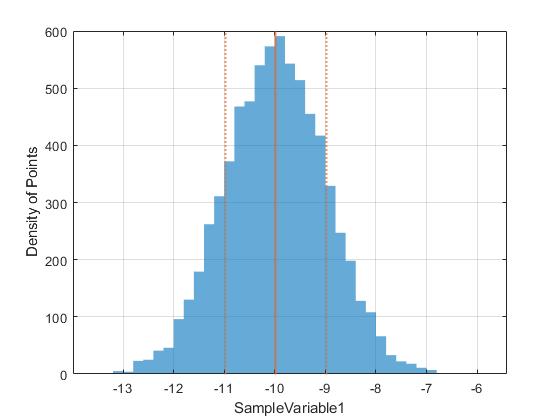

data.avg = mean(chain.df.SampleVariable1);
data.std = std(chain.df.SampleVariable1);

chain.plot.histogram.make();

chain.plot.histogram.target.vline.kws.linewidth = 1.5;
chain.plot.histogram.target.make("values", [ data.avg, nan ] ); % vertical line representing the mean of data

chain.plot.histogram.target.vline.kws.linestyle = ":";
chain.plot.histogram.target.make("values", [ data.avg + data.std, nan ... % horizontal line representing the 1-sigma upper limit of data
                                           ; data.avg - data.std, nan ... % horizontal line representing the 1-sigma lower limit of data
                                           ] ...
                                );

In the above example, each **row** of the input `values` represents **a separate target** to be added to the plot. **By convension, if any component of the input values is **`nan`**, that target corresponding to that component will not be added to the plot.** For example,

chain.plot.histogram.target.make ( "values"  , [ data.avg, nan ] );

is equivalent to,

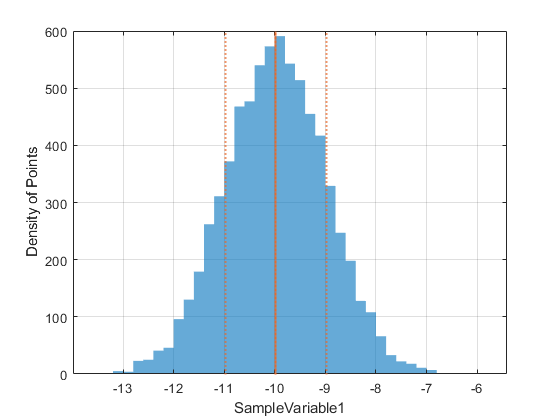

chain.plot.histogram.target.hline.enabled = false;
chain.plot.histogram.target.scatter.enabled = false;
chain.plot.histogram.target.make ( "values"  , [ data.avg, 0 ] ); % or any value other than zero, which will be ignored anyway.

## Exporting figures to external files

To extract a figure to an external PNG file, try,

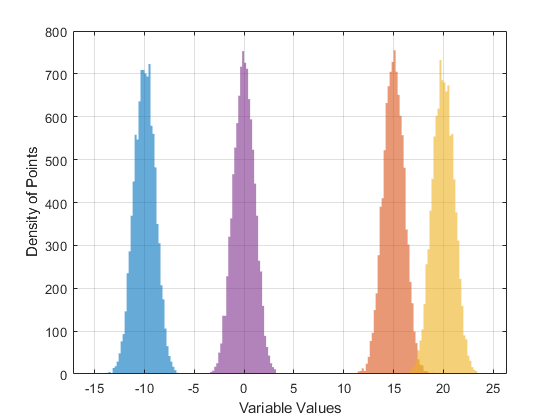

chain.plot.histogram.exportFig("exportedFigure.png","-m4");

The above command will extract the current active figure to an output file with the relatively high resoluton as specified by the flag `-m4`. To make the exported figure smaller, one could specify `-m2` instead. In addition, to generate a figures with background transparency, the flag `-transparent` can be added to the `exportFig` function call,

% chain.plot.histogram.exportFig("exportedFigure.png","-m2 -transparent") % uncomment to export the figure with transparency

**Final Note:**

To see other more sophisticated types of plots that can be automatically made with the ParaMonte visualization tools, visit: [https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/](https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/)